# Does GDP Affect a Country's Olympic Success?

In this example, we'll look at the relationship between a country's gross domestic product (GDP) and its Olympic success.  We will use data from the Summer 2016 games in this example.

## Read Medals Data

We'll start by reading the medals won by each country from a CSV file.  We can plot these values on a geobubble chart where the size of the bubble indicates the number of medals won by that country.  We can see that the United States, China, Russia, and the United Kingdom did quite well.

medals = readtable('medals.csv')

medals = 87×8 table
    Ranking         Country          Gold    Silver    Bronze    Total    Latitude    Longitude
    _______    __________________    ____    ______    ______    _____    ________    _________

       1       {'United States' }     46       37        38       121      38.895      -77.036 
       2       {'United Kingdom'}     27       23        17        67      51.511     -0.11982 
       3       {'China'         }     26       18        26        70      39.904       116.41 
       4       {'Russia'        }     19       18        19        56      55.751       37.618 
       5       {'Germany'       }     17       10        15        42      52.519       13.406 
       6       {'Japan'         }  

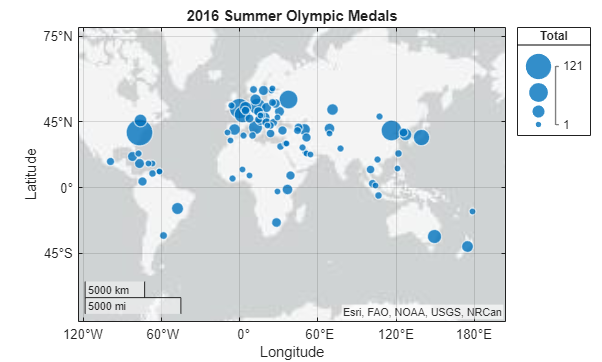

geobubble(medals, 'Latitude','Longitude','SizeVariable','Total','Title','2016 Summer Olympic Medals');

geolimits([-71 77],[-124 204])

## Read GDP data

Read the data for the country's gross domestic product (GDP) from a CSV file.

gdp = readtable('gdp.csv')

gdp = 191×3 table
    Index         Country             GDP    
    _____    __________________    __________

      1      {'United States' }    1.8624e+07
      2      {'China'         }    1.1222e+07
      3      {'Japan'         }    4.9493e+06
      4      {'Germany'       }    3.4792e+06
      5      {'United Kingdom'}    2.6607e+06
      6      {'France'        }    2.4665e+06
      7      {'India'         }    2.2736e+06
      8      {'Italy'         }    1.8602e+06
      9      {'Brazil'        }    1.7931e+06
     10      {'Canada'        }    1.5358e+06
     11      {'South Korea'   }     1.411e+06
     12      {'Russia'        }    1.2833e+06
     13      {'Australia'     }    1.2649e+06
     14      {'Spain'         }    1.2378e+06
     15      {'Mexico'        }    1.0769e+06
     16      {'Indonesia'     }    9.3244e+05


## Join the Medals Data with the GDP Data

We would like to see if there is a relationship between GDP and Olympic success.  To do that, we need to join the medals table with the table that contains the GDP data.  A *join* operation is a way to combine two tables of data using a common key variable -- in this case the country name.  Here we'll use the ***Join Tables*** Live Editor Task to combine the data.

% Join tables
medalsVsGDP = innerjoin(medals,gdp,'Keys','Country')

medalsVsGDP = 80×10 table
    Ranking       Country        Gold    Silver    Bronze    Total    Latitude    Longitude    Index       GDP    
    _______    ______________    ____    ______    ______    _____    ________    _________    _____    __________

      62       {'Algeria'   }      0        2         0        2       36.753        3.042       55     1.5905e+05
      27       {'Argentina' }      3        1         0        4      -34.604      -58.382       21     5.5411e+05
      42       {'Armenia'   }      1        3         0        4       40.183       44.517      134          10572
      10       {'Australia' }      8       11        10   

medalsVsGDP = sortrows(medalsVsGDP, 'Total', 'descend');

## Plot Olympic Medals vs. GDP

The last step is to plot the number of medals won against GDP for each country.  We can see that countries with high GDP tend to do better in the Olympics maybe because they have more resources to spend on their athletes.

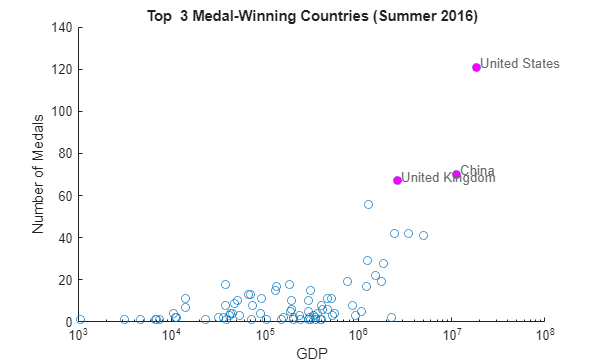

topNum = 3;
topMedals = medalsVsGDP(1:topNum,:);

h_sc = scatter(medalsVsGDP.GDP, medalsVsGDP.Total);
h_sc.Parent.XScale = 'log';
hold on
scatter(topMedals.GDP, topMedals.Total, 'om','filled');
text(1.09*topMedals.GDP, topMedals.Total+2, string(topMedals.Country), ...
    'Color', [0.4 0.4 0.4],'FontSize', 10)
hold off
xlabel('GDP'); ylabel('Number of Medals')
title(sprintf('Top %2d Medal-Winning Countries (Summer 2016)',topNum))

Copyright (c) 2025, The MathWorks, Inc.

## Attribution

Source: [https://www.mathworks.com/products/matlab/live-script-gallery.html](https://www.mathworks.com/products/matlab/live-script-gallery.html)

This example uses Olympic medal data from the Wikipedia article [2016_Summer_Olympics_medal_table](https://en.wikipedia.org/wiki/2016_Summer_Olympics_medal_table) which is released under the [Creative Commons Attribution-Share-Alike License 3.0](https://creativecommons.org/licenses/by-sa/3.0/).  It also uses 2016 GDP data from the Wikipedia article [List_of_countries_by_past_and_projected_GDP_(nominal)](https://en.wikipedia.org/wiki/List_of_countries_by_past_and_projected_GDP_(nominal)) which is released under the [Creative Commons Attribution-Share-Alike License 3.0](https://creativecommons.org/licenses/by-sa/3.0/).